## MoMLib

This is the main file for testing and further development of the MoMLib package/toolbox. It is based upon the starting version established by Robey Beswick as part of his Master's thesis, Stellenbosch University, 2019.

 2019-11-26: Created. MMB.

### Initialization

user = memory

user = struct with fields:
    MaxPossibleArrayBytes: 2.2322e+10
    MemAvailableAllArrays: 2.2322e+10
            MemUsedMATLAB: 3.8780e+09


% close all;
% clear;
% clear all;
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOmom.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOfillplane.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\FoMoM\FOfarfield.c
%       mex GCC='/usr/bin/gcc-7' -O -R2018a src\Jacques\qMoM\qmom.c
%       mex  GCC='/usr/bin/gcc-7' -R2018a src\mom.c
%     mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\qMoM\qfarfield.c
%     mex  GCC='/usr/bin/gcc-7' -R2018a -silent src\Jacques\qMoM\qfillplane.c
FREQUENCY                = 300e6;          % Solution frequancy
c0                       = 2.99792458e8;   % Speed of light in free space
lambda0                  = c0/FREQUENCY;   % Wavelength in free space
k0                       = 2*pi/lambda0;   % free space wavenumber
E_scalfac                = -1;              % plane wave spec
theta_inc                = 0;              % plane wave spec
phi_inc                  = 0;              % plane wave spec
% eta_pol                  = pi/2;              % plane wave spec
eta_pol                  = 0;
flag_planewave           = true;
flag_lumped              = false;           % lumped sources and/or loads are present
interelem_VsrcZload      = [];             % init lumped circuit element specification
mesh_create_option       = 4;              % 1 : Square plate
                                           % 2 : NASTRAN
                                           % 3 : Junction mesh
                                           % 4 : Cylinder
                                           % 5 : Sphere
meshEndcapFlag           = 0;              % For use in mesh option 4
TextOn                   = true;           % mesh visualisation text
flag_mesh_refine_uniform = false;
h_split_num              = 2;

%---------------------------------------------------------------
% Solver select:
%---------------------------------------------------------------
solver                   = 2;              % 1 : RWG
                                           % 2 : First order triangular
                                           % 3 : Zeroth order quadrilateral solver
MBF                      = 1;              % MBF currently only supported for solvers 2,3 and cylinder mesh


### Meshing

rho = 0.2000

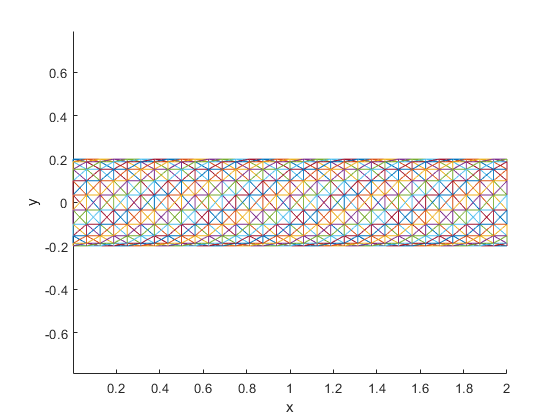

% for iter = 1:5
%oldpath = path;
%path(oldpath,'..\V_6_feat_MemoryFix');

%---------------------------------------------------------------
% Read/create the mesh and visualise --- the end result here is <node_coords>
% and <tri_nodes>, wherever they were obtained from.
%---------------------------------------------------------------

% Create a plate using basic MATLAB commands:
% if mesh_create_option == 1
%     coords_x            = 0:0.05:3;
%     coords_y            = 0:0.02:0.5;
%     [coords_x,coords_y] = meshgrid(coords_x,coords_y);
%     node_coords         = [coords_x(:) coords_y(:)]; % convert matrices to column vectors
%     node_coords(:,3)    = 0; % z-coord
%     tri_nodes           = delaunay(node_coords(:,1:2));
% end
if mesh_create_option == 1
    [node_coords,quad_Elements] = MeshRectanglularPlate(1,1,20,20) ;
    node_coords(:,3) = 0;
    quad_nodes = cell(length(quad_Elements),1);
    for node = 1:length(quad_Elements)
        quad_nodes{node} = [quad_Elements(node,1:4),[0 0 0 0 0 0 0 0]];
    end
%     [revised_triangles,triangles] = QuadtoTri(quad_Elements);
     [tri_nodes,triangles] = QuadtoTri(quad_Elements);
end

% Import from a Nastran file that was created by FEKO:
if mesh_create_option == 2
    %     [node_coords,tri_nodes] = ImportTriangleMeshNastran('bowtie_1.nas');
    [node_coords, tri_nodes] = ImportTriangleMeshNastran('C:\Users\19083688\Desktop\Masters\FEKO Models\Meshes\Hollow_cylinder.nas');
    %node_coords(:,3)        = 0.1*rand(size(node_coords,1),1); % just a test
    interelem_VsrcZload     = [ 43 108 1 0 50 0]; % [tri- tri+ V_src^real V_src^imag Z_load^real Z_load^imag]
    flag_lumped             = true;
    %     interelem_VsrcZload     = [ 43 108 0 0  5e4 0
    %                                 90  80 1 0   0 0
    %                                 82  79 1 0   0 0]; % [tri- tri+ V_src^real V_src^imag Z_load^real Z_load^imag]
end

% Create a custom, junction mesh:
if mesh_create_option == 3
    node_coords = [0   0   0
        1   0   0
        1   1   0
        0   1   0
        0.5 0.5 1];
    tri_nodes   = [1   2   3
        1   3   4
        5   1   3];
end

% Mesh a hollow cylinder
if mesh_create_option == 4
    
%     rho = 0.1+((iter-1)*0.1);
    rho = 0.2
    vertices = 18; % Only even number here for endcap mesh
    % vertices =10 + (9); % Number of vertices
%      Contour = [0 0 0; 1 0 0; 2 0 0; 3 0 0; 4 0 0.1; 5 0 0.2; 6 0.1 0.3; 7 0.2 0.4; 8 0.25 0.5; 9 0.2 0.6; 10 0.2 0.5; 11 0.2 0.4 ]; % Hardcode some contour
%      Contour = [0 0 0; 1 0 0.5; 2 0 1; 3 0 2; 4 0 2; 5 0 1; 6 0 0.5; 7 0 0; 8 0 0; 9 0 0.5; 10 0 1];
%      Contour = [0 0 0; 0.1 0 0; 0.2 0 0; 0.3 0 0; 0.4 0 0; 0.5 0 0];
    Contour = [0 0 0; 1 0 0; 2 0 0];
    Contour = RefineMesh(Contour,4);
    numNodes = length(Contour(:,1))-2;
    [node_coords,quad_nodes, elements] = QuadMesh_v5(Contour,vertices,rho, meshEndcapFlag);
     
    % For coupling testing:
%     node_coords_temp = node_coords ;
%     node_coords_temp(:,2) = node_coords_temp(:,2) + 0.5; % Shift y-axis by 1
%     node_coords = [node_coords;node_coords_temp];
%     elements_temp = elements;
%     elements_temp = elements_temp(:,:) + max(max(elements));
%     elements = [elements;elements_temp];
%     numNodes = (length(Contour(:,1))-2)*2;

    [tri_nodes,triangles] = QuadtoTri(elements, vertices, meshEndcapFlag);
    
     PlotMesh(node_coords,elements, triangles, mod(solver,3));
end


% Mesh a sphere
if mesh_create_option == 5
    radius = 0.5;
    [node_coords, quad_elems] = MeshCube(10,radius);
     quad_nodes = cell(length(quad_elems),1);
    for node = 1:length(quad_elems)
      quad_nodes{node} = [quad_elems(node,1:4),[0 0 0 0 0 0 0 0]]; 
    end
     [tri_nodes,triangles] = QuadtoTri(quad_elems, 1, 0);
%      patch('Faces',tri_nodes,'Vertices',node_coords);
end

% Visualize the raw mesh data:
% PlotTriangleMeshRaw(node_coords,tri_nodes,TextOn);

### Mesh pre-processing & Visualisation

The end result here is <mesh_data> which contains all the necessary derived information from the mesh, required for assigning dofs.

% Create the mesh data, which includes edge definitions and connectivity:
if solver == 3
    % NB: EdgeCalcQuad has functionality for specific directions tailored to cylinders, for help in constructing the MBF
    % If it is desired to run this on generic meshes, comment that code
    [quad_blah,N,basis_supports_quad, quad_Edges,quad_dofs_to_edges] = EdgeCalcQuad(quad_nodes,vertices);
    
    obs_basis_select = {1:N};
    src_basis_select      = {1:N};
    [common_basis_functions, num_obs, num_src] = common_basis(obs_basis_select,src_basis_select);
    quad_dof_idx = (1:N)';
    [new_quads,new_quad_points, new_quad_N, quad_observer_map, quad_source_map] = QuadBasisFunctionSelect(quad_blah ,common_basis_functions,basis_supports_quad,node_coords);
    
else
    
    if solver == 2
        tri_nodes = repelem(tri_nodes,2,1);
    end
    [mesh_data] = CreateMeshData(node_coords,tri_nodes);
%     clear node_coords tri_nodes quad_blah quad_nodes;
    
    % Visualize the processed mesh data:
%     PlotTriangleMeshProcessed(mesh_data,TextOn);
    
    %---------------------------------------------------------------
    % Make uniform mesh refinement.
    %---------------------------------------------------------------
    
    % TODO: This does not work for first order yet.
    if flag_mesh_refine_uniform==true
        [node_coords,tri_nodes] = MeshRefineUniformSplit(mesh_data,h_split_num);
        [mesh_data] = CreateMeshData(node_coords,tri_nodes);
        clear node_coords tri_nodes;
%         PlotTriangleMeshProcessed(mesh_data,TextOn);
    end
    
    %---------------------------------------------------------------
    % Define all the RWG basis functions of the mesh.
    %---------------------------------------------------------------
    
    % Assign the dofs and define each associated basis function:
    [dof_data,num_dofs] = CreateBasisFunctions_New(mesh_data, solver-1, vertices); % 1 for first order
    
%     PlotTriangleMeshDofs(mesh_data,dof_data,TextOn);
    N = num_dofs;
    %---------------------------------------------------------------
    % Reduce the matrix if required; set up the excitation vector, system
    % matrix, and solve.
    %---------------------------------------------------------------
    
    % Build the sparse contributions to the full system due to lumped elements.
    % The contributions can then be suitably reduced according to the selected
    % sources and observers. The reason for not filling this after reduction,
    % is because the lumped elements are specified in terms of the original
    % mesh. Therefore the other option would be to recreate the lumped element
    % specs in terms of the reduced mesh first and then work with that, but
    % such an approach is more complicated, since it would effectively require
    % that the full <dof_data> be reduced, since that is what is needed to
    % assemple the lumped contributions (they are defined in terms of triangle
    % numbers, not just i.t.o. dof numbers and triangle coords).
    if flag_lumped
        [Zlump_rowcolval, Vlump_rowcolval] = CalcZmatVvecLumped(dof_data, num_dofs, mesh_data, interelem_VsrcZload);
    end
    
    % Code to reduce the number of dofs and also to selectively calculate matrix entries/blocks.
    % Define observers and sources required:
    % (V 3.1 allows for basis function selection, the result yields a N_new by
    % N_new matrix, every basis function is both source and observer.)
    obs_basis_select = 1:num_dofs;
    src_basis_select = 1:num_dofs;
    
    % Find the union of the observer and source list and append flags + record
    % total observers and sources to calculate:
    [common_basis_functions, num_obs, num_src, global_to_redu_dofs] = CommonBasis(obs_basis_select,src_basis_select,num_dofs,true);
    
    % Set up reduced set up dofs and mesh nodes, only relevant to the requested
    % common basis functions:
    [reduced_tri_dofs,reduced_node_coords, reduced_num_dofs, ...
        observer_map, source_map] = BasisFunctionSelect(dof_data.tri_dofs,common_basis_functions,dof_data.basis_supports,mesh_data.node_coords);
    
    % 2020/04/06 Edit
    % Merge rows for more compact data struct
    if solver == 2
        for ii = 2:2:length(reduced_tri_dofs)
            reduced_tri_dofs(ii-1,10:15) = reduced_tri_dofs(ii,4:9);
        end
        reduced_tri_dofs = reduced_tri_dofs(1:2:end,:);% Delete extra rows
    else
%         reduced_tri_dofs(:,10:15) = 0;
    end
    
end

<observer_map> and <source_map> should be constructed in CommonBasis, rather than in BasisFunctionSelect


### MoM Calculations

MODE = 0; % set the quadrature accuracy
if solver == 3
    tic  
    [Z_mat] = qmom(new_quad_points, new_quads, new_quad_N, FREQUENCY,int32(quad_observer_map),int32(quad_source_map), num_obs, num_src, MODE);
    toc
    V_vec = qfillPlane(new_quad_points, new_quads, new_quad_N, FREQUENCY,int32(quad_observer_map), num_obs, MODE, theta_inc, phi_inc, eta_pol);

else

    tic
%      [Z_mat] = mom(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map),int32(source_map), num_obs, num_src, MODE);
    [Z_mat] = FOmom(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map),int32(source_map), num_obs, num_src, MODE, solver-1);
    toc
    
    if flag_planewave
        V_vec  = FOfillPlane(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY,int32(observer_map), num_obs, MODE,solver-1, theta_inc, phi_inc, eta_pol);
        % MATLAB version:
        % V_vec = CalcExciteVecPlaneWave(reduced_tri_dofs,reduced_node_coords, observer_map, k0, E_scalfac, theta_inc, phi_inc, eta_pol);
    end

    % Add lumped circuit element contributions to the reduced Z and V, by
    % obtaining the contributions in sparse format and then adding to the
    % system:
    if flag_lumped
        [Zlump_reduced, Vlump_reduced] = FinalZmatVvecLumped(Zlump_rowcolval, Vlump_rowcolval, global_to_redu_dofs, num_obs, num_src, observer_map, source_map);
        Z_mat = Z_mat + Zlump_reduced;
        V_vec = V_vec + Vlump_reduced;
    end
end


3 3: 991944
3 3: 218664
4 4: 79632
6 6: 22176
7 7: 94752
7 RAR: 8064

If it were done when 'tis done, then 'twere well It were done quickly


Elapsed time is 73.954521 seconds.


MODE = 0

If it were done when 'tis done, then 'twere well It were done quickly


### MBF Calculation

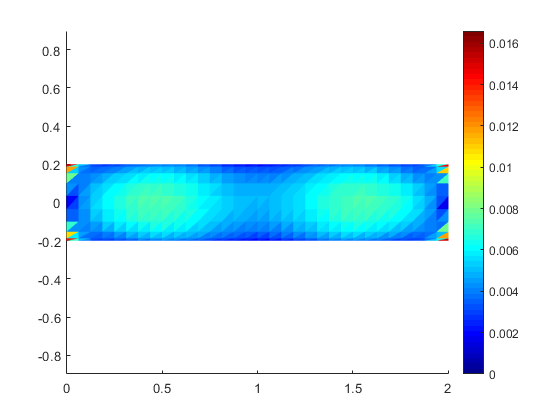

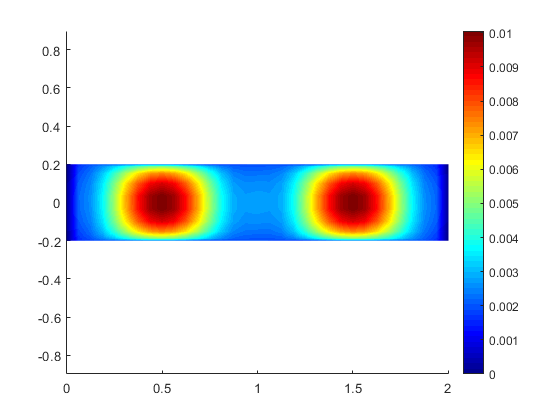

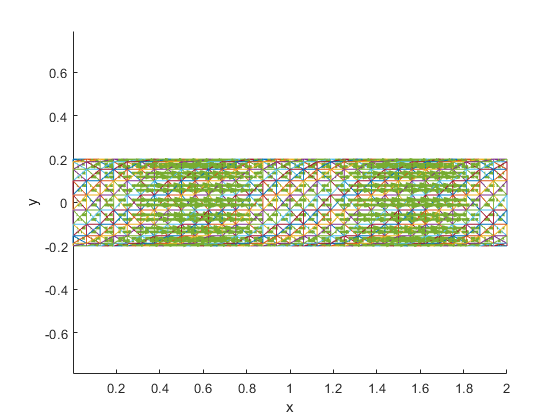

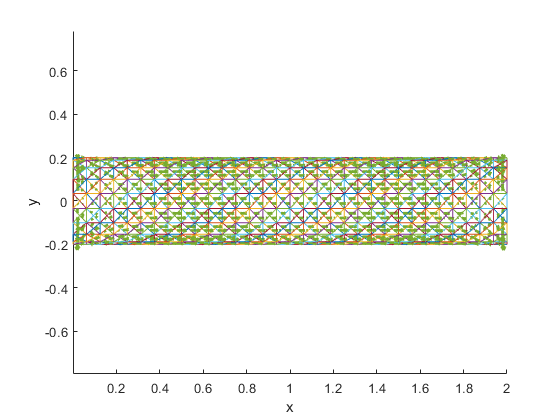

% U_Mat1 = U_Mat(:,4:6:end); % Plot only one MBF
% U_Mat1(end-vertices+1:end,end) = U_Mat(end-vertices+1:end,end-2);
% U_Mat2 = U_Mat(:,5:6:end); % Plot only one MBF
% U_Mat2(end-vertices+1:end,end) = U_Mat(end-vertices+1:end,end-1);
% U_Mat3 = U_Mat(:,6:6:end);
% U_Mat3(end-vertices+1:end,end) = U_Mat(end-vertices+1:end,end);
% U_Mat4 = zeros(N, numNodes*3);
% U_Mat4(:,1:3:end) = U_Mat1;
% U_Mat4(:,2:3:end) = U_Mat2;
% U_Mat4(:,3:3:end) = U_Mat2;
% U_Mat = U_Mat4;
% U_Mat = U_Mat(:,1:3);
numMBF =6;
if solver == 3
    if MBF == 1
        
        U_Mat = [];
        [U_Mat] = SelectDOFMBF(basis_supports_quad, vertices,numNodes,numMBF);
        %         U_Mat = zeros(length(basis_supports_quad),1);
        [U_Mat] = SelectDOFMBF_2(basis_supports_quad, vertices, U_Mat,numNodes,numMBF);
%         PlotTriangleMeshDofsMBFQuad(node_coords,quad_blah,TextOn, U_Mat, quad_Edges, quad_dofs_to_edges);
    end
else
    if MBF == 1
        U_Mat = [];
        [U_Mat, DOF_mat1, DOF_mat2, DOF_mat3] = SelectDOFMBF_FO_New(mesh_data, dof_data, vertices, numMBF, numNodes, reduced_tri_dofs,meshEndcapFlag);
        if meshEndcapFlag
            [U_Mat, DOF_mat, theta1, theta2] = SelectDOFMBF_FO_New_v3(mesh_data, dof_data, vertices ,numMBF, numNodes, reduced_tri_dofs, meshEndcapFlag, U_Mat);
        else
            [U_Mat, DOF_mat] = SelectDOFMBF_FO_New_v3(mesh_data, dof_data, vertices ,numMBF, numNodes, reduced_tri_dofs, meshEndcapFlag, U_Mat);
        end
        
        U_Mat(:,~any(U_Mat,1)) = []; % Remove zero columns
        
        %                U_Mat(:,end-5:end) = []; % Remove endcap circ MBF
        %         U_Mat(3881:3960,:) = 0;
        %         U_Mat(:,end-2:end) = [];
        %         U_Mat(:,end-5:end-3) = [];
        %         [U_Mat] = SelectDOFMBF_FO_New_2( vertices, numNodes,numMBF,reduced_tri_dofs, U_Mat, meshEndcapFlag);
        % PlotMesh(mesh_data.node_coords,elements, triangles, mod(solver,3));
        % hold on
        % PlotTriangleMeshDofsMBF(mesh_data,dof_data,TextOn, U_Mat);
        % hold off
    end
end
% U_Mat = U_Mat(:,1:9);
% Solve:
if MBF == 0
    I_vec = Z_mat\V_vec;
else
    Z_mat_redu = U_Mat.'*Z_mat*U_Mat;
    V_vec_redu = U_Mat.'*V_vec;
    Alpha_Vec_Redu = Z_mat_redu\V_vec_redu;
    New_N = size(Alpha_Vec_Redu,1);
    I_vec = U_Mat*Alpha_Vec_Redu;
    if meshEndcapFlag == 1
        [I_vec] = ScaleEndCapCurrent(DOF_mat1, DOF_mat, theta1, theta2, I_vec);
    end
end

I_vec_norm = Z_mat\V_vec;

% Post-processing
% Calculate and plot the surface current distribution, and current direction.
% Calculate the surface current density at the three vertices of all mesh triangle:
if solver == 3
    num_quad = size(new_quads,1);
    [quads_vertices_currents] = CalcElementsCurrentsQuad(I_vec, new_quads, quad_dof_idx, num_quad, node_coords);
    
     % Calculate centroid and vertex current magnitudes:
    quad_currents_cent = zeros(num_quad,1);
    quad_currents_dir = zeros(num_quad,3);
    quad_currents_vert = zeros(num_quad,4);
    for ii = 1:num_quad
        J_centroid              = (1/4)*[1 1 1 1]*squeeze(quads_vertices_currents(ii,1:4,1:3)); % Add each component at all 3 vertices and average
        for kk = 1:4 % Cycle of 4 vertices of quad
             quad_currents_dir(ii,1) =  quad_currents_dir(ii,1) + quads_vertices_currents(ii,kk,1);
             quad_currents_dir(ii,2) =  quad_currents_dir(ii,2) + quads_vertices_currents(ii,kk,2);
             quad_currents_dir(ii,3) =  quad_currents_dir(ii,3) + quads_vertices_currents(ii,kk,3);
        end

        quad_currents_cent(ii,1) = sqrt(abs(J_centroid*J_centroid'));
        for jj = 1:4
            J_vertex                 = squeeze(quads_vertices_currents(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            quad_currents_vert(ii,jj) = sqrt(abs(J_vertex*J_vertex')); % Magnitude
        end
    end
    quad_currents_dir_real = real(quad_currents_dir);
    quad_currents_dir_imag = imag(quad_currents_dir);
else
%      num_tri = size(dof_data.tri_dofs,1);
num_tri = size(reduced_tri_dofs,1);
 tri_dof_idx = (1:N)';
%  tri_dof_idx = dof_data.tri_dofs_idx;

 [triangles_vertices_currents] = CalcElementsCurrentsFO(I_vec, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords, solver -1, mesh_data);
 [triangles_vertices_currents_norm] = CalcElementsCurrentsFO(I_vec_norm, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords, solver -1, mesh_data);
%   [triangles_vertices_currents] = CalcElementsCurrents(I_vec, dof_data.tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords);
% if (solver == 1)
% %     [triangles_vertices_currents] = CalcElementsCurrents(I_vec, reduced_tri_dofs, tri_dof_idx, num_tri, mesh_data.node_coords);
% num_tri = size(mesh_data.tri_nodes,1);
% [triangles_vertices_currents] = CalcElementsCurrents(I_vec, dof_data.tri_dofs, dof_data.tri_dofs_idx, num_tri, mesh_data.node_coords);
% end

  % Calculate centroid and vertex current magnitudes:
    tri_currents_cent = zeros(num_tri,1);
    tri_currents_cent_norm = zeros(num_tri,1);
    tri_currents_dir = zeros(num_tri,3);
    tri_currents_dir_norm = zeros(num_tri,3);
    tri_currents_vert = zeros(num_tri,3);
    tri_currents_vert_norm = zeros(num_tri,3);
    for ii = 1:num_tri
        J_centroid              = (1/3)*[1 1 1]*squeeze(triangles_vertices_currents(ii,1:3,1:3)); % Add each component at all 3 vertices and average
        J_centroid_norm         = (1/3)*[1 1 1]*squeeze(triangles_vertices_currents_norm(ii,1:3,1:3)); % Add each component at all 3 vertices and average
        tri_currents_cent(ii,1) = sqrt(abs(J_centroid*J_centroid'));
        tri_currents_cent_norm(ii,1) = sqrt(abs(J_centroid_norm*J_centroid_norm'));
         for kk = 1:3 % Cycle of 3 vertices of triangle
             tri_currents_dir(ii,1) =  tri_currents_dir(ii,1) + triangles_vertices_currents(ii,kk,1); 
             tri_currents_dir(ii,2) =  tri_currents_dir(ii,2) + triangles_vertices_currents(ii,kk,2);
             tri_currents_dir(ii,3) =  tri_currents_dir(ii,3) + triangles_vertices_currents(ii,kk,3);
             
             tri_currents_dir_norm(ii,1) =  tri_currents_dir_norm(ii,1) + triangles_vertices_currents_norm(ii,kk,1); 
             tri_currents_dir_norm(ii,2) =  tri_currents_dir_norm(ii,2) + triangles_vertices_currents_norm(ii,kk,2);
             tri_currents_dir_norm(ii,3) =  tri_currents_dir_norm(ii,3) + triangles_vertices_currents_norm(ii,kk,3);
         end
         tri_currents_dir = real(tri_currents_dir);
         tri_currents_dir_norm = real(tri_currents_dir_norm);
        
        
        for jj = 1:3
            J_vertex                 = squeeze(triangles_vertices_currents(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            J_vertex_norm            = squeeze(triangles_vertices_currents_norm(ii,jj,1:3)).'; % non-conjugate transpose to make this a row vector
            tri_currents_vert(ii,jj) = sqrt(abs(J_vertex*J_vertex')); % Magnitude
            tri_currents_vert_norm(ii,jj) = sqrt(abs(J_vertex_norm*J_vertex_norm')); % Magnitude
        end
    end
end

% Calculate diff:
diff_currents = tri_currents_vert - tri_currents_vert_norm;
diff_currents_dir = tri_currents_dir - tri_currents_dir_norm;

% Visualize the current:
if solver == 3
    PlotCurrent3DQuad(1,false,quad_blah,node_coords,quad_currents_vert);
    PlotCurrentDir3D(0,quad_blah,node_coords,quad_currents_dir_real,quad_currents_dir_imag);
elseif solver == 2
    
% [x_axis, current_norm, current_MBF] = plotNodeCurrent(I_vec,I_vec_norm,DOF_mat1,DOF_mat2,DOF_mat3,DOF_mat, numNodes,meshEndcapFlag);

    PlotCurrent3D(0,false,mesh_data.tri_nodes(1:2:end,:), mesh_data.node_coords, tri_currents_cent_norm);
     PlotCurrent3D(1,false,mesh_data.tri_nodes(1:2:end,:), mesh_data.node_coords,tri_currents_vert);
%       PlotCurrent3D(1,false,mesh_data.tri_nodes(1:2:end,:), mesh_data.node_coords,tri_currents_vert_norm);
%      PlotCurrent3D(1,false,mesh_data.tri_nodes(1:2:end,:), mesh_data.node_coords,diff_currents);
    
    PlotCurrentDir3D(1,mesh_data.tri_nodes(1:2:end,:),mesh_data.node_coords,tri_currents_dir);
    PlotCurrentDir3D(1,mesh_data.tri_nodes(1:2:end,:),mesh_data.node_coords,tri_currents_dir_norm);
elseif solver == 1
    PlotCurrent3D(0,false,mesh_data.tri_nodes, mesh_data.node_coords,tri_currents_cent);
    PlotCurrent3D(1,false,mesh_data.tri_nodes,mesh_data.node_coords,tri_currents_vert);
    PlotCurrentDir3D(1,mesh_data.tri_nodes,mesh_data.node_coords,tri_currents_dir);
end


%---------------------------------------------------------------
% Custom impedance calculation for the 'bowtie_1.nas' mesh, when excited at the neck: edge nodes 24 and 28; dof number 49.
%---------------------------------------------------------------

if flag_lumped
    if num_dofs > 48
        edgevectemp = mesh_data.node_coords(28,:) - mesh_data.node_coords(24,:);
        ELength     = sqrt(edgevectemp*edgevectemp');
        Z_11        = 1/(ELength*I_vec(49,1))
%         disp('General source impedance calculation must still be implemented');
    end
end

%---------------------------------------------------------------
% Calculate and plot the farfield.
%---------------------------------------------------------------

% The output of the farfield routine has this row format:
% THETA     PHI     magn{Etheta} phase{Etheta} magn{Ephi} phase{Ephi}
%   1        2            3           4            5          6
plane               = 'XZ'; % set the observation plane: 'XY' or 'XZ' or 'YZ'
delta_angle_degrees = 2;    % degree increment for observation directions
if solver == 3
    [farfield_XY] = qfarfield(new_quad_points, new_quads, new_quad_N, FREQUENCY, I_vec, delta_angle_degrees, plane);
    [farfield_XY_norm] = qfarfield(new_quad_points, new_quads, new_quad_N, FREQUENCY, I_vec_norm, delta_angle_degrees, plane);
elseif solver == 2
    [farfield_XY] = FOfarfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec, delta_angle_degrees, plane, solver-1);
    [farfield_XY_norm] = FOfarfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec_norm, delta_angle_degrees, plane, solver-1);
else
    [farfield_XY] = farfield(reduced_node_coords, reduced_tri_dofs, reduced_num_dofs, FREQUENCY, I_vec, delta_angle_degrees, plane);
end


If it were done when 'tis done, then 'twere well It were done quickly



If it were done when 'tis done, then 'twere well It were done quickly


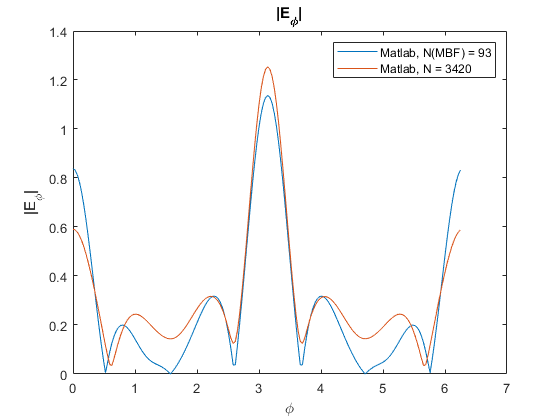


% disp('<farfield> routine still needs some generalisation work');
figure;
plot(farfield_XY(:,1),sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2));
hold on

% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\MoM Codes\V_3.6_feat_speed\Jacques\FEKO\Hollow_Cylinder_0.1.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\MoM Codes\V_3.6_feat_speed\Jacques\FEKO\Hollow_Cylinder_ZPlaneWave.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\hollow_cyl_theta_45.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\hollow_cyl_endcaps_xz.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\endcap_cyl_0.3r.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\thin_wire_0.2.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\cyl_endcap_theta_45_0.5r.txt');
%  [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\cyl_endcap_0.4r.txt');
 
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\hollow_cyl_0.1_theta_45.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\0.1_cyl_endcaps.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\hollow_cyl_8m_xz.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\Masters\MoMLib\src\Jacques\FEKO\sphere_0.5.txt');
% [E_field_FEKO] = feko_farfield_extract('C:\Users\19083688\Desktop\MoM Codes\V_3.6_feat_plane_wave_MBF_qmom\Jacques\FEKO\Square_plate_scattered.txt');
% semilogy
% plot(E_field_FEKO(:,1)*(pi/180),sqrt(E_field_FEKO(:,3).^2 + E_field_FEKO(:,5).^2), '+-');
title('|E_{\phi}|')
if MBF == 1
    plot(farfield_XY_norm(:,1),sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2));
%     legend("Matlab, N(MBF) = " + New_N,  "FEKO", "Matlab, N = " + N)
    legend("Matlab, N(MBF) = " + New_N,  "Matlab, N = " + N)
else
    legend("Matlab, N = " + N, "FEKO")
end
xlabel('\phi')
ylabel('|E_{\phi}|');

[errAbsFF(1), errRelFF(1)] = pNormError(sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2), sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2), 2)
[errAbsI(1), errRelI(1)] = pNormError(I_vec, I_vec_norm, 2)
% err1 = pNormError(sqrt(farfield_XY(:,3).^2 + farfield_XY(:,5).^2), sqrt(farfield_XY_norm(:,3).^2 + farfield_XY_norm(:,5).^2), 2)
% end